# Spazio operativo primario e secondario del robot RRR planare

## Spazio operativo primario

Lo spazio operativo primario è $WS_1 = \{ \underline{p}\in\mathbb{R}^2:||\underline{p}||\leq 3l \}$.

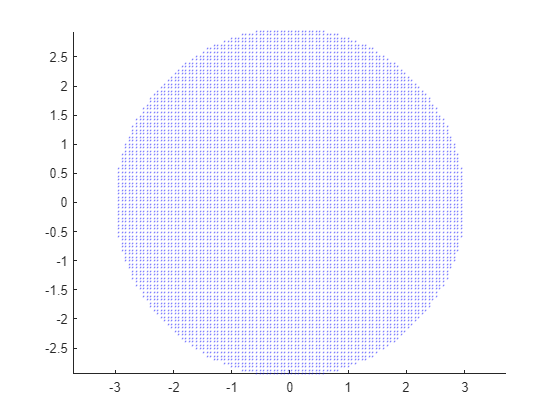

% parametri cerchio
center1 = [0, 0];
radius1 = 1+1+1;
 
figure
drawWS(center1, radius1, 'b');
axis equal

## Spazio operativo secondario

Lo spazio operativo secondario è $WS_2 = \{ \underline{p}\in\mathbb{R}^2:||\underline{p}||\leq l \}$. 

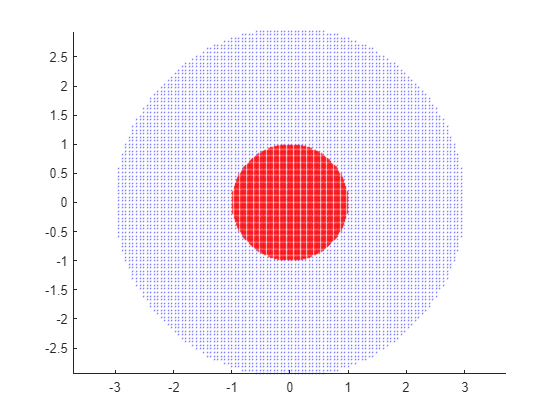

center2 = [0, 0];
radius2 = 1;

figure
drawWS(center1, radius1, 'b')
hold on
drawWS(center2, radius2, 'r')

## Alcune configurazioni

### Configurazione limite per $WS_1$

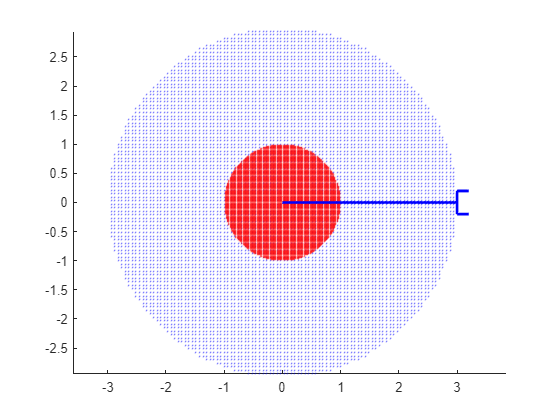

figure
drawWS(center1, radius1, 'b')
hold on
drawWS(center2, radius2, 'r')
drawPlanarRobot([1,1,1],[0,0,0])

### Esempio in $WS_2
$

Si vuole posizionare l'end-effector in $[p_x, p_y] = [0.1, -0.5] \in WS_2$ con orientamento $\phi = \frac{\pi}{2}$. Per fare ciò è necessario ricavare le variabili di giunto $[q_1,q_2,q_3]$.

Dalla cinematica inversa sappiamo che

$q_2 = atandue(s_2, c_2)$ dove $\begin{cases}
        c_2 = \frac{\hat{x}^2 + \hat{y}^2 - l_1^2 - l_2^2}{2l_1l_2} = \frac{\hat{x}^2 + \hat{y}^2 -2}{2} = \frac{(p_x^2+p_y^2+1-2(p_xc_{\phi}+p_ys_{\phi}))-2}{2}\\
        s_2 =  \sqrt{1-c_2^2}
 \end{cases}
$

dato che $\hat{x}^2+\hat{y}^2 = p_x^2+p_y^2+1-2(p_xc_{\phi}+p_ys_{\phi})$ essendo $\hat{x} = p_x - l_3c_{\phi}$ e $\hat{y} = p_y-l_3s_{\phi}$.

% q2
px = 0.1; % x desiderata
py = -0.5; % y desiderata
phi = pi/2; % orientamento desiderato
c2 = (px^2+py^2+1-2*(px*cos(phi)+py*sin(phi))-2)/2;
s2 = sqrt(1-c2^2);
q2 = atan2(s2, c2)

q2 = 1.4404

Dalla cinematica inversa sappiano che

$q_1 = atandue(s_1,c_1)$ dove $\begin{cases}
        c_1 = \frac{\hat{x}(l_1+l_2c_2) -+\hat{y}l_2s_2}{\hat{x}^2 + \hat{y}^2} =
\frac{(p_x-l_3c_{\phi})(l_1+l_2c_2) +(p_y-l_3s_{\phi})l_2s_2}{p_x^2+p_y^2+1-2(p_xc_{\phi}+p_ys_{\phi})} = \\
        s_1 = \frac{\hat{y}(l_1+l_2c_2) - \hat{x}l_2s_2}{\hat{x}^2 + \hat{y}^2}  = \frac{(p_y-l_3s_{\phi})(l_1+l_2c_2) - (p_x-l_3c_{\phi})l_2s_2}{p_x^2+p_y^2+1-2(p_xc_{\phi}+p_ys_{\phi})}
    \end{cases}$

dato che $\hat{x}^2+\hat{y}^2 = p_x^2+p_y^2+1-2(p_xc_{\phi}+p_ys_{\phi})$ essendo $\hat{x} = p_x - l_3c_{\phi}$ e $\hat{y} = p_y-l_3s_{\phi}$.

% q1
c1 = ((px-cos(phi))*(1+c2)+(py-sin(phi))*s2)/(px^2+py^2+1-2*(px*cos(phi)+py*sin(phi)));
s1 = ((py-sin(phi))*(1+c2)-(px-cos(phi))*s2)/(px^2+py^2+1-2*(px*cos(phi)+py*sin(phi)));
q1 = atan2(s1, c1);
% q3
q3 = phi-q1-q2

q3 = 2.3548

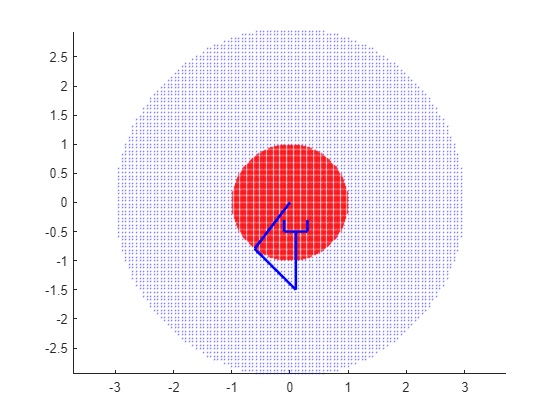

figure
drawWS(center1, radius1, 'b')
hold on
drawWS(center2, radius2, 'r')
drawPlanarRobot([1,1,1],[q1,q2,q3])

Si vuole ora posizionare l'end-effector nella stessa posizione $[p_x, p_y] = [0.1, -0.5] \in WS_2$ ma con orientamento $\phi = \frac{5\pi}{6}$.

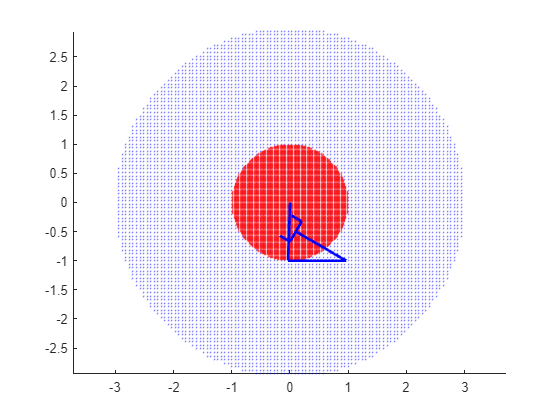

% q2
px = 0.1; % x desiderata
py = -0.5; % y desiderata
phi = 5*pi/6; % orientamento desiderato
c2 = (px^2+py^2+1-2*(px*cos(phi)+py*sin(phi))-2)/2;
s2 = sqrt(1-c2^2);
q2 = atan2(s2, c2);
% q1
c1 = ((px-cos(phi))*(1+c2)+(py-sin(phi))*s2)/(px^2+py^2+1-2*(px*cos(phi)+py*sin(phi)));
s1 = ((py-sin(phi))*(1+c2)-(px-cos(phi))*s2)/(px^2+py^2+1-2*(px*cos(phi)+py*sin(phi)));
q1 = atan2(s1, c1);
% q3
q3 = phi-q1-q2;

figure
drawWS(center1, radius1, 'b')
hold on
drawWS(center2, radius2, 'r')
drawPlanarRobot([1,1,1],[q1,q2,q3])